# Modelo 6

Es un modelo más realista 


$$\begin{array}{l}
\frac{\textrm{dP}}{\textrm{dt}}=\left(b-d\right)\cdot P\\
b=\textrm{ratio}\;\textrm{de}\;\textrm{nacimiento}\;o\;\textrm{ganar}\;\textrm{dinero}\\
d=\textrm{ratio}\;\textrm{de}\;\textrm{muerte}\;o\;\textrm{sacar}\;\textrm{dinero}\\
k=b-d\\
\frac{1}{d}=\textrm{tasa}\;\textrm{de}\;\textrm{vida}\;\textrm{útil}\;\textrm{estimada}
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
syms P(t) P0 t0 b d k

edo = diff(P, t, 1) == (b-d)*P;
cond = [P(t0)==P0];
P(t) = dsolve(edo, cond)

$$P(t) = P_{0}\,{\mathrm{e}}^{t\,\left(b-d\right)}\,{\mathrm{e}}^{-t_{0}\,\left(b-d\right)}$$


% con k = b - d
P(t) = subs(P,b-d,k)

$$P(t) = P_{0}\,{\mathrm{e}}^{k\,t}\,{\mathrm{e}}^{-k\,t_{0}}$$


$$\begin{array}{l}
\frac{1}{d}\;\;=\textrm{tasa}\;\textrm{de}\;\textrm{vida}\;\textrm{útil}\;\textrm{estimada}\\
R_{o\;} =\;\frac{b}{d}=\textrm{nº}\;\textrm{de}\;\textrm{descendientes}\;\textrm{esperados}\;o\;\textrm{tasa}\;\textrm{de}\;\textrm{reproducción}\\
\textrm{Si}\;R_o <1\to \textrm{epidemia}\;\textrm{remite}\\
\textrm{Si}\;R_o >1\to \textrm{epidemia}
\end{array}$$


#### 2. Sustitución de valores iniciales y constante r 

(Tomar k = r)

r_values = [0.02, 0.1, 0.05];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(r_values);

#### 3. Gráfica para cada caso

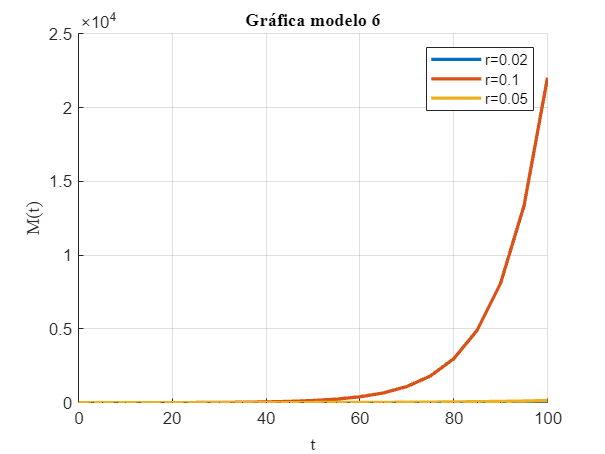

figure;
hold on;
for i = 1:n
    M_subs = subs(P, [k t0, P0], [r_values(i), ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['r=' num2str(r_values(i))]);
end

xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Gráfica modelo 6','FontName','latex');
legend('show');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra (para r = 0.8, los valores de M(t) son menores).

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=r\cdot M\\
M=0
\end{array}$$


o cuando $b=d$, teniendo que la población se mantendría sin aumentar ni disminuir

syms P b d
eq =(b-d)*P == 0;
P = solve(eq,P)

$$P = 0$$

Observamos en la gráfica que efectivamente se estabiliza, cuando $M=0$ en cualquiera de los casos. El estado estacionario o de equilibrio es **trivial**.

### Por circuito en Simulink

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 15;
solver.step = 1;

Nombre del modelo

model_name = "modelo3";

Condiciones iniciales y constantes del modelo:

k_values = [0,0,0];
r_values = [0.1, 0.2, -0.1];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(r_values);

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;
P1 = signals{1}.Values.Data

P1 =     0.1000    0.2000   -0.1000
    0.1030    0.2124   -0.0970
    0.1062    0.2255   -0.0942
    0.1094    0.2394   -0.0914
    0.1127    0.2542   -0.0887
    0.1162    0.2700   -0.0861
    0.1197    0.2867   -0.0835
    0.1234    0.3044   -0.0811
    0.1271    0.3232   -0.0787
    0.1310    0.3432   -0.0763


P = signals{2}.Values.Data

P =     1.0000    1.0000    1.0000
    1.0305    1.0618    0.9704
    1.0618    1.1275    0.9418
    1.0942    1.1972    0.9139
    1.1275    1.2712    0.8869
    1.1618    1.3499    0.8607
    1.1972    1.4333    0.8353
    1.2337    1.5220    0.8106
    1.2712    1.6161    0.7866
    1.3100    1.7160    0.7634


signal_time = signals{1}.Values.Time;

#### Gráfica 1

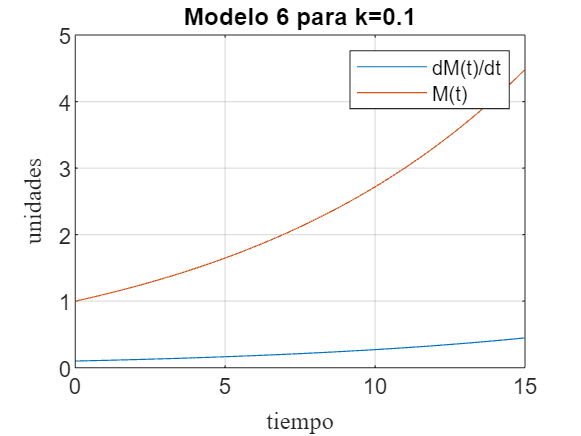

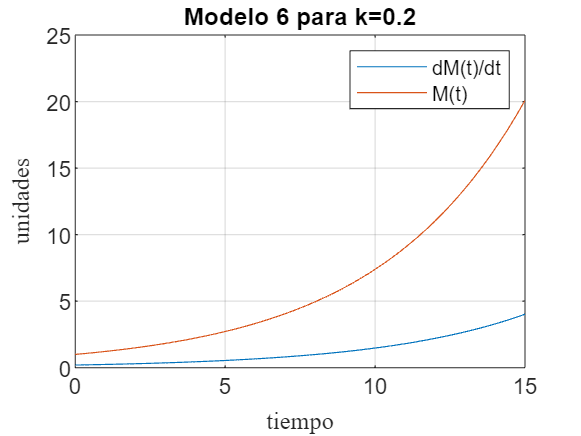

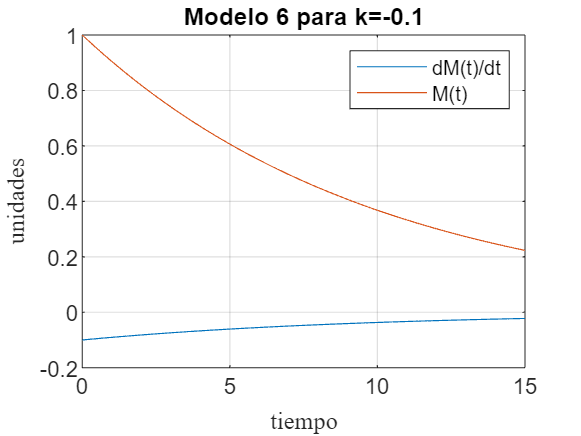

[m, n] = size(P1);
for i =1:n
    figure
    plot(signal_time, P1(:,i))
    hold on
    plot(signal_time, P(:,i))
    grid on
    xlabel("tiempo","FontName","latex");
    ylabel("unidades","FontName","latex");
    title(['Modelo 6 para k=' num2str(r_values(i))]);
    legend('dM(t)/dt','M(t)');
    hold off
end 

#### Gráfica 2

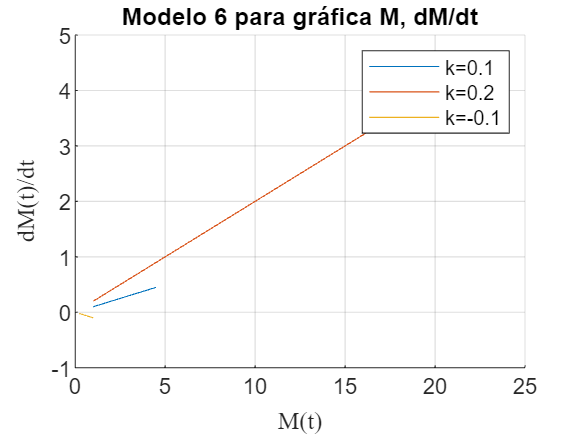

[m, n] = size(P1);
figure;
hold on;
for i =1:n
    plot(P(:,i), P1(:,i), 'DisplayName', ['k=' num2str(r_values(i))])
    grid on
    xlabel("M(t)","FontName","latex");
    ylabel("dM(t)/dt","FontName","latex");
    title('Modelo 6 para gráfica M, dM/dt');
    hold on
end 
legend('show')

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

**Decorador de la función sim de MATLAB**

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

Se utiliza el bloque Out1 para cada señal.